## Identifying a model for the AC generator

## Generate input data

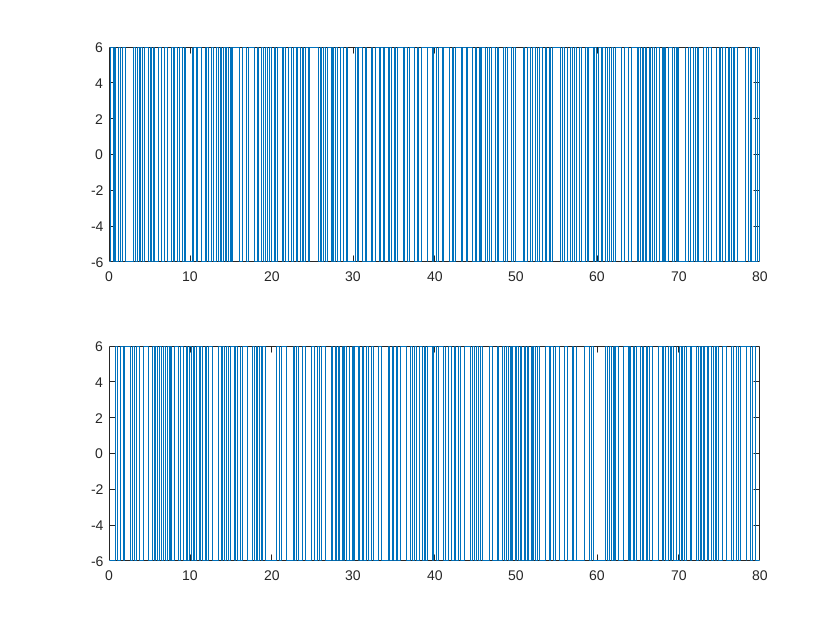


h = 0.1;
N = 800;
Tfinal = N*h;   
uu = idinput(N, 'rbs', [0, 0.5]);
inputMagnitude = 6;
u1 = inputMagnitude*uu(1:N/2);
u1v = inputMagnitude*uu(N/2+1:N);
t = (1:N)'*h;
input1 = cat(2, t, cat(1, u1, flipud(u1)));
input1v = cat(2, t, cat(1, u1v, flipud(u1v)));

figure(1)
subplot(211)
stairs(input1(:,1), input1(:,2))
subplot(212)
stairs(input1v(:,1), input1v(:,2))

### Run simulation

out = sim('ac_generator_sysid', Tfinal) 

out =   Simulink.SimulationOutput:

                 simout: [1x1 timeseries] 
                   tout: [81822x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


## Load data

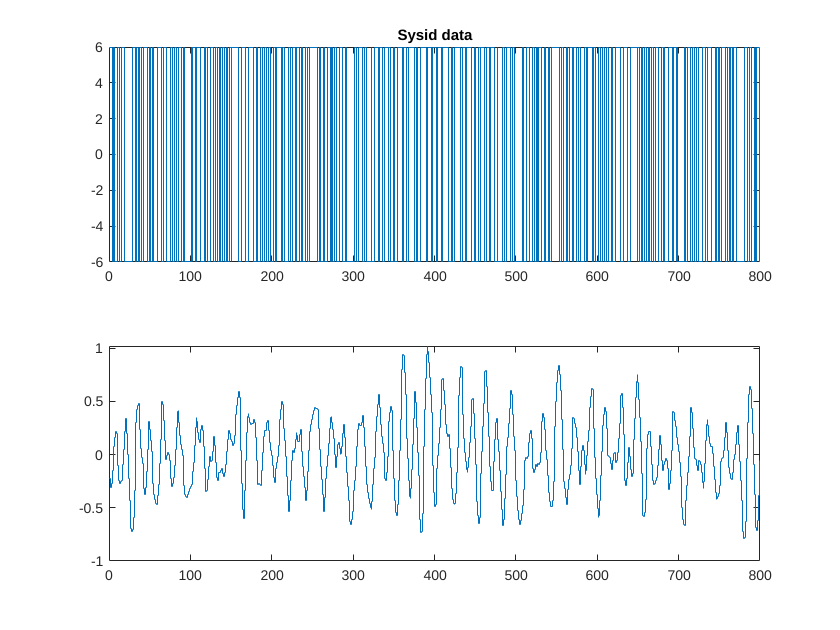

uident = out.simout.Data(3:end,1);
yident = out.simout.Data(3:end,2);
uval = out.simout.Data(3:end,3);
yval = out.simout.Data(3:end,4);

iddta1 = iddata(yident,uident, h);
valdta1 = iddata(yval, uval, h);

figure()
subplot(211);
stairs(uident)
title('Sysid data')
subplot(212)
stairs(yident)

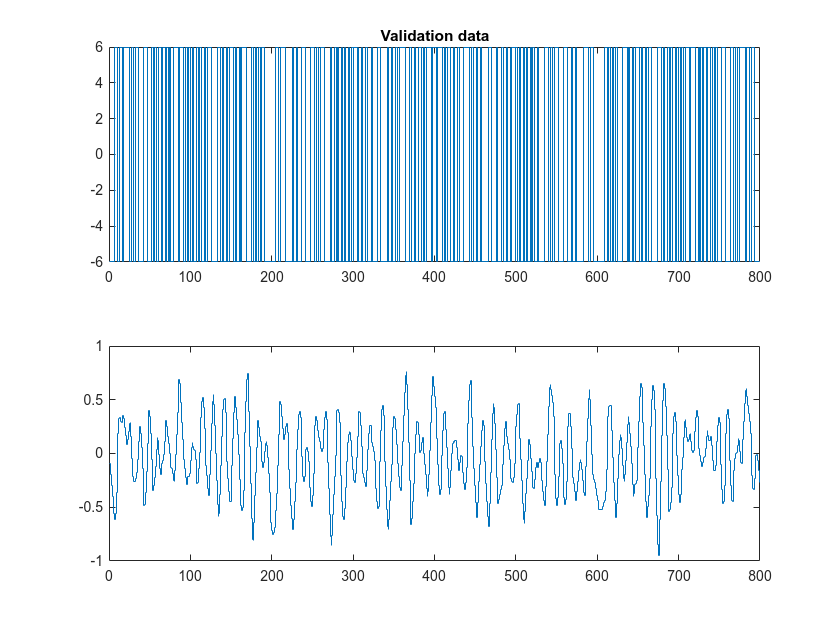


figure()
subplot(211);
stairs(uval)
title('Validation data')
subplot(212)
stairs(yval)

## Estimate models

## Compare models

compare()

Check the Akaike Information Criterion

aic()

## Export models for use in Simulink

[num, den] = tfdata(tf(mybestmodel))
figure()
clf
pzmap(mybestmodel)
